
clear; clc;

## 产生数据

data = iris_dataset;
gnd_one = [ones(1,50),ones(1,50)*2,ones(1,50)*3];
gnd = [ones(50,1),zeros(50,2);zeros(50,1),ones(50,1),zeros(50,1);zeros(50,2),ones(50,1)];
seq = randperm(150);
x = data(:,seq(1:100))';
y = gnd(seq(1:100)',:);
Test = data(:,seq(101:end))';
gnd_Test = gnd(seq(101:end)',:);
gnd_one_test = gnd_one(seq(101:end));



## 训练神经网络

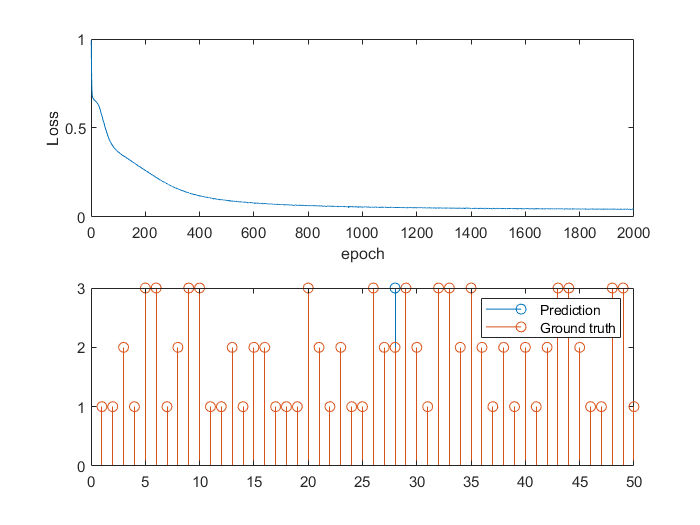

% 输入，隐层，输出维数
d0 = 4; d1 = 10; d2 = 3;

%  初始化W1,W2,b1,b2
W1 = sqrt(2/d0)*randn(d1,d0);
b1 = zeros(d1,1);
W2 = sqrt(2/d1)*randn(d2,d1);
b2 = zeros(d2,1);


for ii = 1 : 2000  % 迭代2000个epoch
    % 采用随机梯度的方法，对每个样本调整一次权值，每个epoch，将样本先随机打乱次序进行训练
    P = randperm(100);
    X = x(P,:);
    Y = y(P,:);
    
    alpha = 0.01;
    
    % 针对每个打乱次序的样本调整权值
    for i = 1 : 100 
        Z1 = W1 * X(i,:)'+b1;
        h = mysigmoid(Z1);
        Z2 = W2 * h + b2;
        y_out = mysigmoid(Z2);
        loss(i) = norm(Y(i,:)'-y_out)^2;
        % 计算梯度
        [delta2_W2,delta2_b2,delta1_W1,delta1_b1] = my_grad(X(i,:)',y_out,Y(i,:)',Z1,Z2,W2,d0,d1,d2);
        
        % 权值更新
        W1 = W1 - alpha* delta1_W1;
        b1 = b1 - alpha* delta1_b1';
        W2 = W2 - alpha* delta2_W2;
        b2 = b2 - alpha* delta2_b2';
    end
    % 记下b2，一维的好画图
    % 计算Loss
    loss_epoch(ii) =  1/100*sum(loss);
end

%% 测试
for i = 1 : 50
    Z1 = W1 * Test(i,:)'+b1;
    h = mysigmoid(Z1);
    Z2 = W2 * h + b2;
    temp = mysigmoid(Z2); 
    y_test(i,:) = temp';
    [~,lainx] = max(y_test(i,:));
    test_la(i) = lainx;
end

subplot(2,1,1)
plot(loss_epoch)
ylabel('Loss')
xlabel('epoch')
subplot(2,1,2)
stem(test_la);
hold on
stem(gnd_one_test);
legend('Prediction','Ground truth')